# RVC2: Chapter 2

clear all
close all
clc

## 2.1.1.1 2d rotation

R = rot2(0.2)

R =     0.9801   -0.1987
    0.1987    0.9801



det(R)

ans = 1


det(R*R)

ans = 1


syms theta
R = rot2(theta)

$$R = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

simplify(R*R)

$$ans = \left(\begin{array}{cc} \cos\left(2\,\theta \right) & -\sin\left(2\,\theta \right)\\ \sin\left(2\,\theta \right) & \cos\left(2\,\theta \right) \end{array}\right)$$

simplify(det(R))

$$ans = 1$$

## 2.1.1.2 2d matrix exponential

R = rot2(0.3)

R =     0.9553   -0.2955
    0.2955    0.9553



S = logm(R)

S =          0   -0.3000
    0.3000         0



vex(S)

ans = 0.3000


expm(S)

ans =     0.9553   -0.2955
    0.2955    0.9553



R = rot2(0.3)

R =     0.9553   -0.2955
    0.2955    0.9553



R = expm(  skew(0.3)  )

R =     0.9553   -0.2955
    0.2955    0.9553


## Sidebar: skew symmetric matrices (page 25)

skew(2)

ans =      0    -2
     2     0


vex(ans)

ans = 2

## 2.1.2.1 2D pose

T1 = transl2(1, 2) * trot2(30, 'deg')

T1 =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000



plotvol([0 5 0 5]);
trplot2(T1, 'frame', '1', 'color', 'b')

T2 = transl2(2, 1)

T2 =      1     0     2
     0     1     1
     0     0     1



trplot2(T2, 'frame', '2', 'color', 'r');

T3 = T1*T2

T3 =     0.8660   -0.5000    2.2321
    0.5000    0.8660    3.8660
         0         0    1.0000


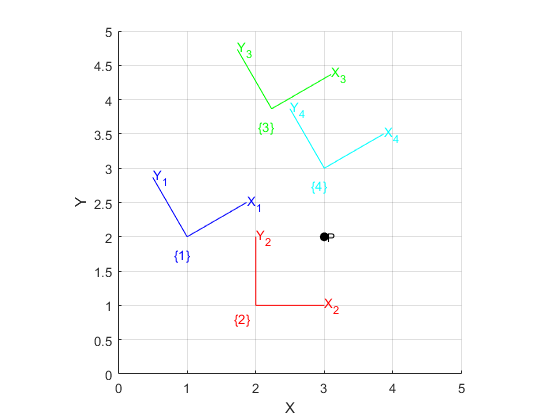


trplot2(T3, 'frame', '3', 'color', 'g');

T4 = T2*T1;
trplot2(T4, 'frame', '4', 'color', 'c');

P = [3 ; 2 ];

plot_point(P, 'label', 'P', 'solid', 'ko');

P1 = inv(T1) * [P; 1]

P1 =     1.7321
   -1.0000
    1.0000



h2e( inv(T1) * e2h(P) )

ans =     1.7321
   -1.0000


## 2.1.2.2 2D centres of rotation

clf
plotvol([-5 4 -1 4.5]);
T0 = eye(3,3);
trplot2(T0, 'frame', '0');
X = transl2(2, 3);
trplot2(X, 'frame', 'X');

R = trot2(2);

trplot2(R*X, 'framelabel', 'RX', 'color', 'r');
trplot2(X*R, 'framelabel', 'XR', 'color', 'r');

C = [1 2]';
plot_point(C, 'label', ' C', 'textcolor', 'k', 'solid', 'ko')


RC = transl2(C) * R * transl2(-C)

RC =    -0.4161   -0.9093    3.2347
    0.9093   -0.4161    1.9230
         0         0    1.0000


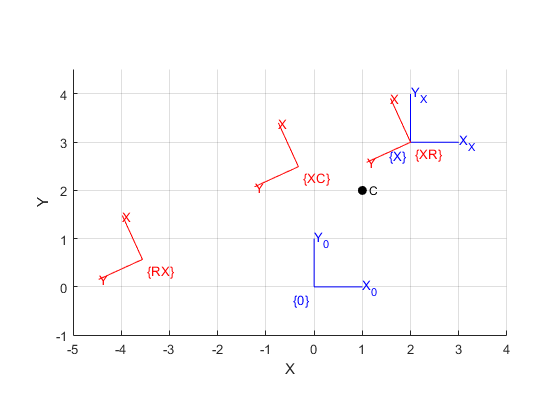

trplot2(RC*X, 'framelabel', 'XC', 'color', 'r');

## 2.1.2.3 2D twists

tw = Twist('R', C)

 
tw = 
( 2  -1; 1 )



tw.T(2)

ans =    -0.4161   -0.9093    3.2347
    0.9093   -0.4161    1.9230
         0         0    1.0000



tw.pole'

ans =      1     2



tw = Twist('T', [1 1])

 
tw = 
( 0.70711  0.70711; 0 )



tw.T(sqrt(2))

ans =      1     0     1
     0     1     1
     0     0     1



T = transl2(2, 3) * trot2(0.5)

T =     0.8776   -0.4794    2.0000
    0.4794    0.8776    3.0000
         0         0    1.0000



tw = Twist(T)

 
tw = 
( 2.7082  2.4372; 0.5 )


tw.T

ans =     0.8776   -0.4794    2.0000
    0.4794    0.8776    3.0000
         0         0    1.0000


## 2.2.1.1 Orthonormal rotation matrix

R = rotx(pi/2)

R =      1     0     0
     0     0    -1
     0     1     0


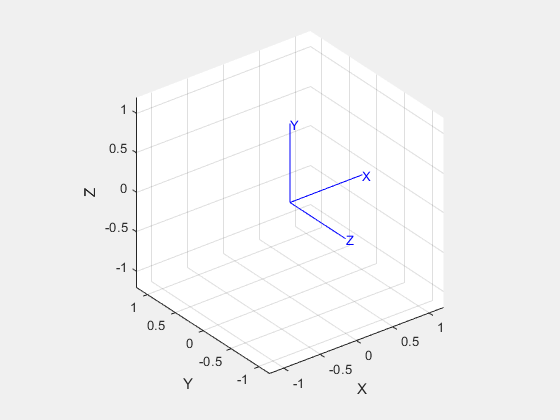


clf
trplot(R)

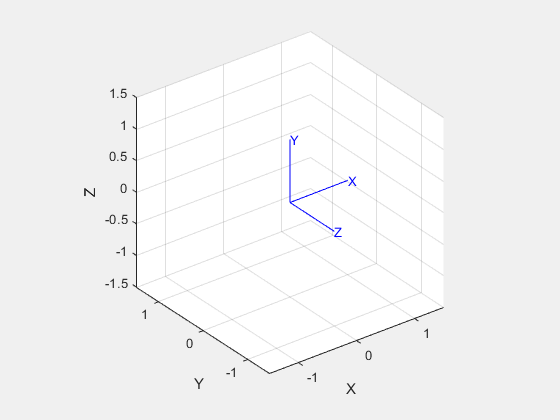


tranimate(R)

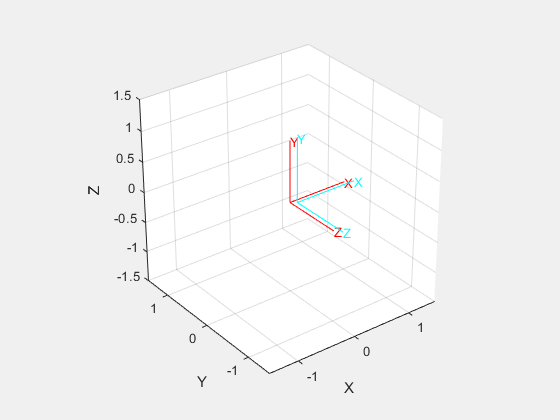


tranimate(R, '3d')


R = rotx(pi/2) * roty(pi/2)

R =      0     0     1
     1     0     0
     0     1     0



roty(pi/2)*rotx(pi/2)

ans =      0     1     0
     0     0    -1
    -1     0     0


## 2.2.1.2  3-angle representation

Euler angles

R = rotz(0.1) * roty(0.2) * rotz(0.3);

R = eul2r(0.1, 0.2, 0.3)

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801



gamma = tr2eul(R)

gamma =     0.1000    0.2000    0.3000



R = eul2r(0.1 , -0.2, 0.3)

R =     0.9021   -0.3836   -0.1977
    0.3875    0.9216   -0.0198
    0.1898   -0.0587    0.9801



tr2eul(R)

ans =    -3.0416    0.2000   -2.8416



eul2r(ans)

ans =     0.9021   -0.3836   -0.1977
    0.3875    0.9216   -0.0198
    0.1898   -0.0587    0.9801



R = eul2r(0.1, 0, 0.3)

R =     0.9211   -0.3894         0
    0.3894    0.9211         0
         0         0    1.0000



tr2eul(R)

ans =          0         0    0.4000


RPY angles

R = rpy2r(0.1, 0.2, 0.3)

R =     0.9363   -0.2751    0.2184
    0.2896    0.9564   -0.0370
   -0.1987    0.0978    0.9752



gamma = tr2rpy(R)

gamma =     0.1000    0.2000    0.3000



% tripleangle

## 2.2.1.4  2-vector representation

a = [1 0 0]';
o = [0 1 0]';
R = oa2r(o, a)

R =      0     0     1
     0     1     0
    -1     0     0


## 2.2.1.5 Rotation about arbitrary vector

R = rpy2r(0.1 , 0.2, 0.3);

[theta, v] = tr2angvec(R)

theta = 0.3655

v =     0.1886    0.5834    0.7900



[x,e] = eig(R)

x =    0.6944 + 0.0000i   0.6944 + 0.0000i   0.1886 + 0.0000i
  -0.0792 - 0.5688i  -0.0792 + 0.5688i   0.5834 + 0.0000i
  -0.1073 + 0.4200i  -0.1073 - 0.4200i   0.7900 + 0.0000i


e =    0.9339 + 0.3574i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.9339 - 0.3574i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i



theta = angle(e(1,1))

theta = 0.3655


R = angvec2r(pi/2, [1 0 0])

R =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


## 2.2.1.6 matrix exponentials

R = rotx(0.3)

R =     1.0000         0         0
         0    0.9553   -0.2955
         0    0.2955    0.9553



S = logm(R) 

S =          0         0         0
         0         0   -0.3000
         0    0.3000         0



vex(S)'

ans =     0.3000         0         0



[th,w] = trlog(R)

th = 0.3000

w =     1.0000
         0
         0



expm(S)

ans =     1.0000         0         0
         0    0.9553   -0.2955
         0    0.2955    0.9553



R = rotx(0.3);

R = expm( skew([1 0 0]) * 0.3 );

## Sidebar: skew symmetric matrices  (page 43)

skew([1 2 3])

ans =      0    -3     2
     3     0    -1
    -2     1     0



vex(ans)'

ans =      1     2     3


## 2.2.1.7 Unit quaternions

q = UnitQuaternion( rpy2tr(0.1, 0.2, 0.3)  )

 
q = 
 
0.98335 < 0.034271, 0.10602, 0.14357 >
 



q = q * q;

inv(q)

 
ans = 
 
0.93394 < -0.0674, -0.20851, -0.28236 >
 



q*inv(q)

 
ans = 
 
1 < 0, 0, 0 >
 



q/q

 
ans = 
 
1 < 0, 0, 0 >
 



q.R

ans =     0.7536   -0.4993    0.4275
    0.5555    0.8315   -0.0081
   -0.3514    0.2436    0.9040


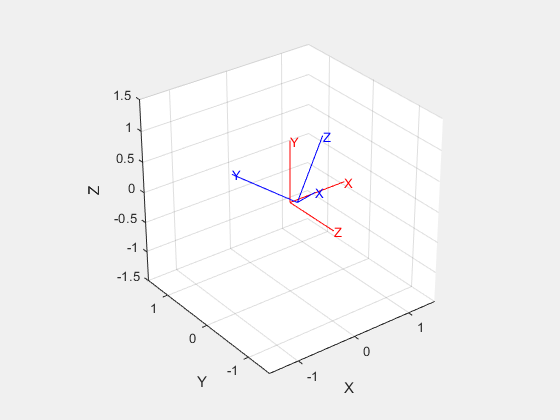


q.plot()


q*[1 0 0]'

ans =     0.7536
    0.5555
   -0.3514


## 2.2.2.1 homogeneous transformation matrix

T = transl(1, 0, 0) * trotx(pi/2) * transl(0, 1, 0)

T =      1     0     0     1
     0     0    -1     0
     0     1     0     1
     0     0     0     1


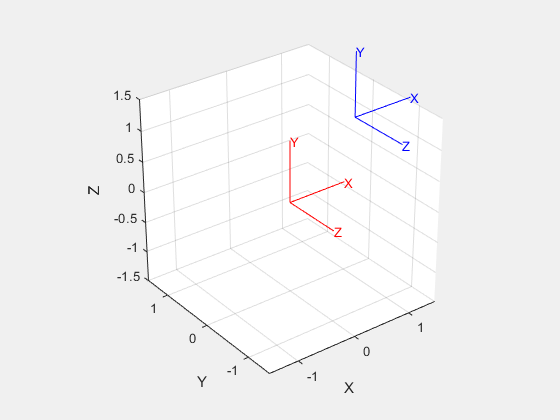


trplot(T)


t2r(T)

ans =      1     0     0
     0     0    -1
     0     1     0



transl(T)'

ans =      1     0     1


## 2.2.2.3 Twists in 3d

tw = Twist('R', [1 0 0], [0 0 0])

 
tw = 
( 0  0  0; 1  0  0 )



tw.T(0.3)

ans =     1.0000         0         0         0
         0    0.9553   -0.2955         0
         0    0.2955    0.9553         0
         0         0         0    1.0000



tw = Twist('T', [0 1 0])

 
tw = 
( 0  1  0; 0  0  0 )



tw.T(2)

ans =      1     0     0     0
     0     1     0     2
     0     0     1     0
     0     0     0     1



X = transl(3, 4, -4);

angles = [0:0.3:15];

tw = Twist('R', [0 0 1], [2 3 2], 0.5);

clf
tranimate( @(theta) tw.T(theta) * X, angles, ...
     'length', 0.5, 'retain', 'rgb', 'notext');

L = tw.line

 
L = 
{ -3  2  -1; 0  0  1 }


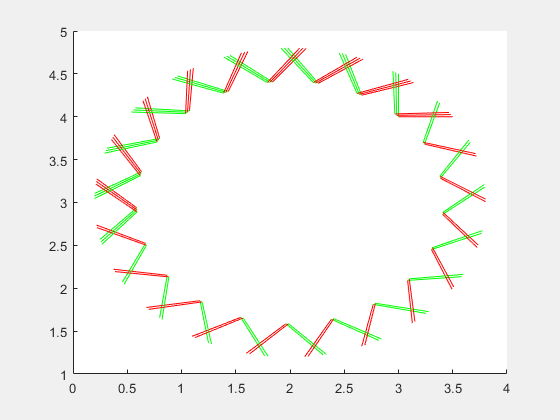

 
L.plot('k:', 'LineWidth', 2)

 
T = transl(1, 2, 3) * eul2tr(0.3, 0.4, 0.5);
tw = Twist(T)

 
tw = 
( 1.1204  1.6446  3.1778; 0.041006  0.4087  0.78907 )



tw.pitch

ans = 3.2256


tw.theta

ans = 0.8896


tw.pole'

ans =     0.0011    0.8473   -0.4389


## 2.3.1 Normalization

R = eye(3,3);
det(R) - 1

ans = 0


for i=1:100
       R = R * rpy2r(0.2, 0.3, 0.4);
end
det(R) - 1

ans = 4.2188e-15


R = trnorm(R);
det(R) - 1

ans = -1.1102e-16


q = q.unit();

q2 = q;  % ADDITION
q = q .* q2;

## more twists

tw = Twist('R', [1 0 0], [0 0 0])

 
tw = 
( 0  0  0; 1  0  0 )



tw.S'

ans =      0     0     0     1     0     0


tw.v'

ans =      0     0     0


tw.w'

ans =      1     0     0



tw.se 

ans =      0     0     0     0
     0     0    -1     0
     0     1     0     0
     0     0     0     0



tw.T(0.3)

ans =     1.0000         0         0         0
         0    0.9553   -0.2955         0
         0    0.2955    0.9553         0
         0         0         0    1.0000



tw.line

 
ans = 
{ -0  -0  -0; 1  0  0 }



t2 = tw * tw

 
t2 = 
( 0  0  0; 2  0  0 )


tr2angvec(t2.T)

Rotation: 2.000000 rad x [1.000000 0.000000 0.000000]


## 2.4 Using the toolbox

T1 = SE2(1, 2, 30, 'deg')

 

T1 = 
    0.8660   -0.5000         1
    0.5000    0.8660         2
         0         0         1


about T1

T1 [SE2] : 1x1 (72 bytes)



T1 

 

T1 = 
    0.8660   -0.5000         1
    0.5000    0.8660         2
         0         0         1



T1.T 

ans =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


about ans

ans [double] : 3x3 (72 bytes)



inv(T1) * P

ans =     1.7321
   -1.0000
